# Imagem a preto e branco 

% Link da imagem que vamos utilizar:
% https://www.reddit.com/r/PixelArtTutorials/comments/1jc8dfj/64x64_pixel_art_from_online_image_not_mine/?tl=pt-br

imagem = imread("charmander_cinzento.jpg"); 

A = double(imagem);

[U, S, V] = svd(A); % decomposicao svd
valores_singulares = diag(S);
total_valores = length(valores_singulares);
fprintf('%d\n',total_valores);

512



denominador = sum(valores_singulares.^2);
percentagens = [1, 10, 25, 50, 75];

fprintf('O número total de valores singulares obtidos é: %d', total_valores); % alínea (i)

O número total de valores singulares obtidos é: 512

Valores retidos:  1% (p =   5) | Qualidade:  94.08630%


Valores retidos: 10% (p =  51) | Qualidade:  99.99243%


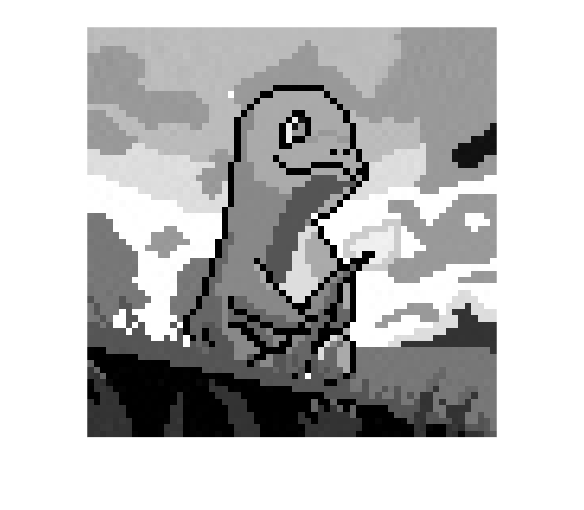

Valores retidos: 25% (p = 128) | Qualidade: 100.00000%


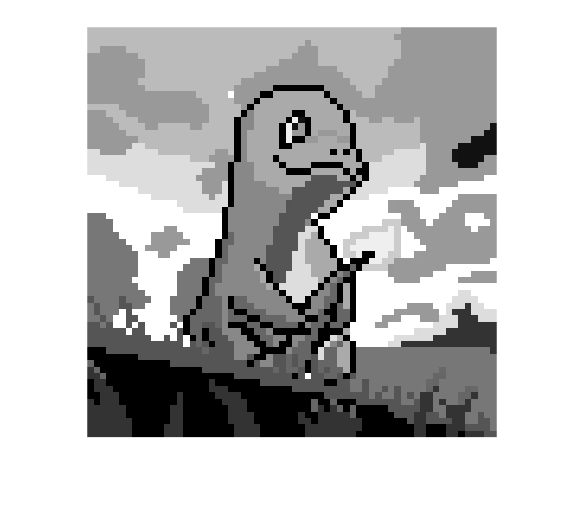

Valores retidos: 50% (p = 256) | Qualidade: 100.00000%


Valores retidos: 75% (p = 384) | Qualidade: 100.00000%




for i = 1:length(percentagens)
    prec = percentagens(i);

    p = round((prec / 100) * length(valores_singulares)); %o numero de valores singulares que vao sobrar

    U_p = U(:, 1:p);
    S_p = S(1:p, 1:p);
    V_p = V(:, 1:p);
    A_simplificada = U_p * S_p * V_p';

    numerador = sum(valores_singulares(1:p).^2);
    sigma = numerador/denominador;
    qualidade_percentagem = sigma*100;

    fprintf('Valores retidos: %2d%% (p = %3d) | Qualidade: %9.5f%%\n', prec, p, qualidade_percentagem);
    % gera um texto a indicar o numero de valores singulares retidos e a
    % qualidade da imagem final

    figure;
    imshow(uint8(A_simplificada)); % mostra a imagem com a respetiva reducao de valores singulares
end

## Imagem a cores

Passo 1:


  Canal R:  1% valores (p =   5) | Qualidade:  90.8480%


  Canal G:  1% valores (p =   5) | Qualidade:  92.0246%


  Canal B:  1% valores (p =   5) | Qualidade:  94.5754%


---------------------------------------------------------------


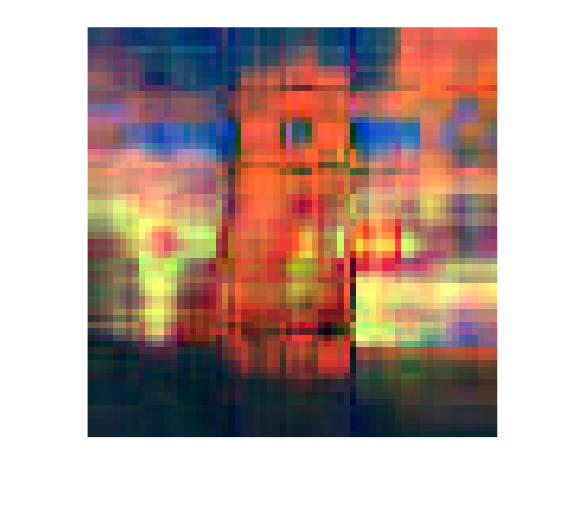

Passo 2:


  Canal R: 10% valores (p =  51) | Qualidade:  99.9830%


  Canal G: 10% valores (p =  51) | Qualidade:  99.9844%


  Canal B: 10% valores (p =  51) | Qualidade:  99.9643%


---------------------------------------------------------------


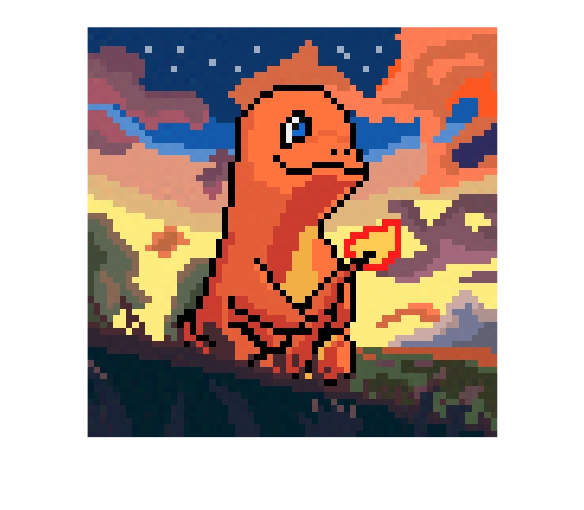

Passo 3:


  Canal R: 25% valores (p = 128) | Qualidade:  99.9998%


  Canal G: 25% valores (p = 128) | Qualidade:  99.9998%


  Canal B: 25% valores (p = 128) | Qualidade:  99.9991%


---------------------------------------------------------------


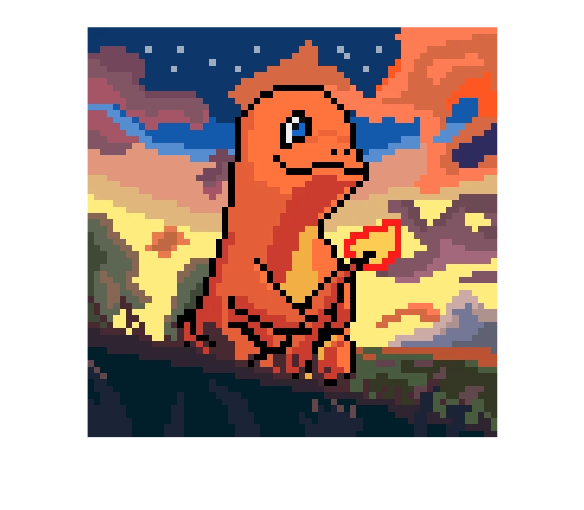

Passo 4:


  Canal R: 50% valores (p = 256) | Qualidade: 100.0000%


  Canal G: 50% valores (p = 256) | Qualidade: 100.0000%


  Canal B: 50% valores (p = 256) | Qualidade:  99.9999%


---------------------------------------------------------------


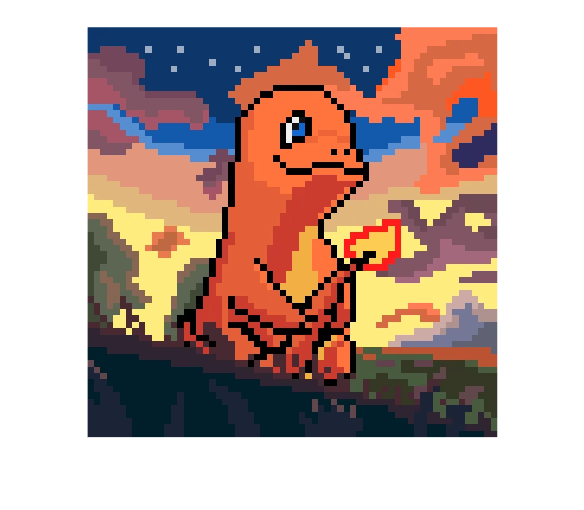

Passo 5:


  Canal R: 75% valores (p = 384) | Qualidade: 100.0000%


  Canal G: 75% valores (p = 384) | Qualidade: 100.0000%


  Canal B: 75% valores (p = 384) | Qualidade: 100.0000%


---------------------------------------------------------------


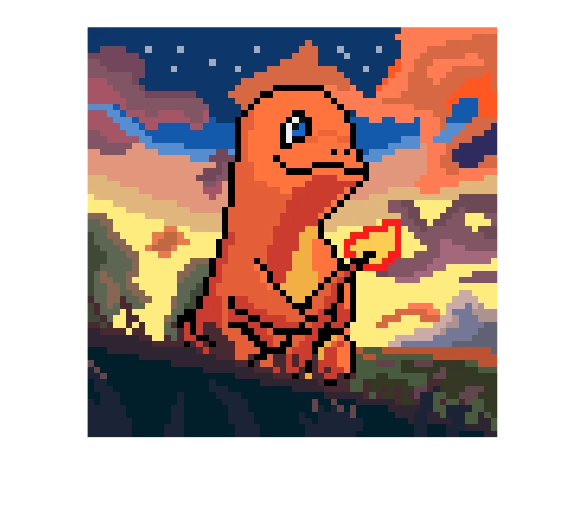

Passo 6:


  Canal R:  0% valores (p =   0) | Qualidade:   0.0000%


  Canal G: 100% valores (p = 512) | Qualidade: 100.0000%


  Canal B: 100% valores (p = 512) | Qualidade: 100.0000%


---------------------------------------------------------------


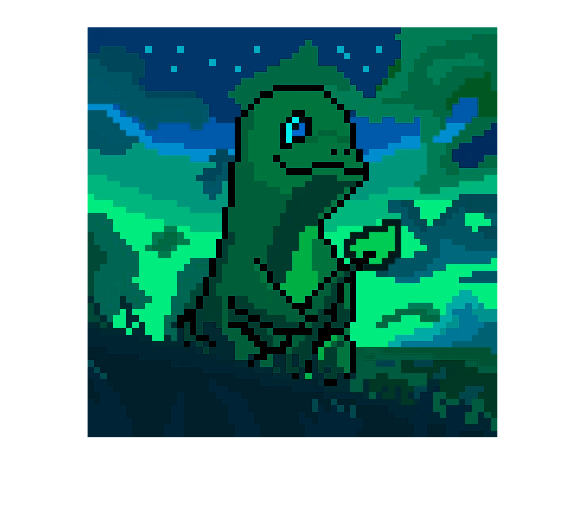

Passo 7:


  Canal R: 100% valores (p = 512) | Qualidade: 100.0000%


  Canal G:  0% valores (p =   0) | Qualidade:   0.0000%


  Canal B: 100% valores (p = 512) | Qualidade: 100.0000%


---------------------------------------------------------------


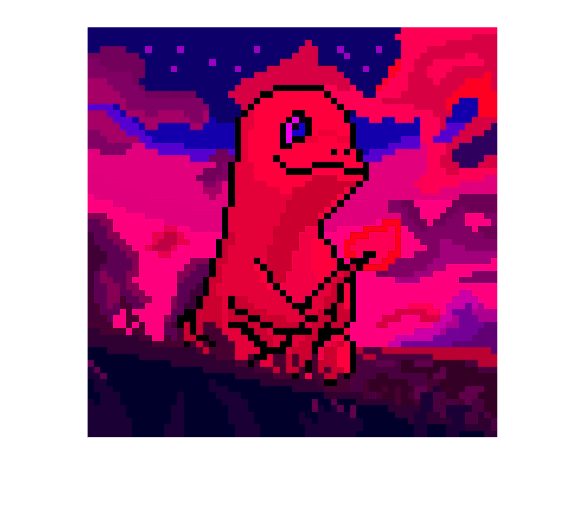

Passo 8:


  Canal R: 100% valores (p = 512) | Qualidade: 100.0000%


  Canal G: 100% valores (p = 512) | Qualidade: 100.0000%


  Canal B:  0% valores (p =   0) | Qualidade:   0.0000%


---------------------------------------------------------------


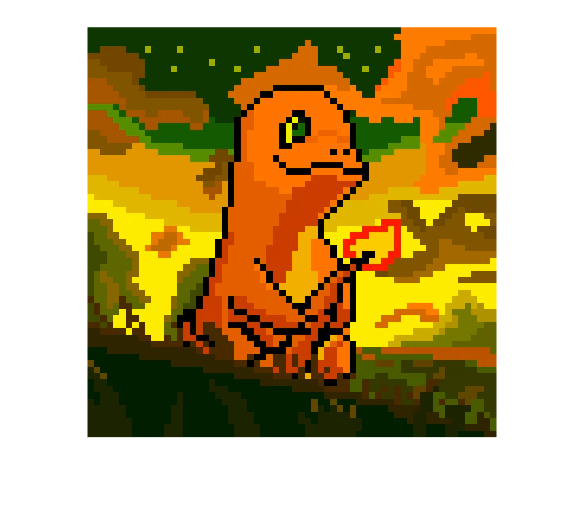

imagem_cor = imread("charmander.jpg");

B = double(imagem_cor);

R = B(:, :, 1); % da-nos cada uma das diferentes matrizes de cada cor
G = B(:, :, 2); 
B = B(:, :, 3);

[U_R, S_R, V_R] = svd(R); % decomposicao svd de cada uma das matrizes
[U_G, S_G, V_G] = svd(G);
[U_B, S_B, V_B] = svd(B);

valores_singulares_R = diag(S_R);
valores_singulares_G = diag(S_G);
valores_singulares_B = diag(S_B);

total_valores_R = length(valores_singulares_R);
total_valores_G = length(valores_singulares_G);
total_valores_B = length(valores_singulares_B);

percentagens_R = [1, 10, 25, 50, 75,0,100,100];
percentagens_G = [1, 10, 25, 50, 75,100,0,100]; 
percentagens_B = [1, 10, 25, 50, 75,100,100,0];
% Separar as percentagem em 3 vetores diferentes danos mais liberdades da   
% combinacao das diferentes camadas do RGB, foi o que nos permitiu fazer as
% imagens onde removemos uma das cores

%contudo é importante ter o cuidade que o código só corre se os 3 vetores
%tiverem o mesmo tamanho



denominador_R = sum(valores_singulares_R.^2);
denominador_G = sum(valores_singulares_G.^2);
denominador_B = sum(valores_singulares_B.^2);

for i=1:length(percentagens_R) % este codigo e analogo ao da imagem em preto e branco 
    prec_R = percentagens_R(i);
    prec_G = percentagens_G(i);
    prec_B = percentagens_B(i);

    p_R = round((prec_R / 100) * total_valores_R);
    p_G = round((prec_G / 100) * total_valores_G);
    p_B = round((prec_B / 100) * total_valores_B);

    U_p_R = U_R(:, 1:p_R);
    S_p_R = S_R(1:p_R, 1:p_R);
    V_p_R = V_R(:, 1:p_R);
    R_simplificado = U_p_R * S_p_R * V_p_R';

    U_p_G = U_G(:, 1:p_G);
    S_p_G = S_G(1:p_G, 1:p_G);
    V_p_G = V_G(:, 1:p_G);
    G_simplificado = U_p_G * S_p_G * V_p_G';

    U_p_B = U_B(:, 1:p_B);
    S_p_B = S_B(1:p_B, 1:p_B);
    V_p_B = V_B(:, 1:p_B);
    B_simplificado = U_p_B * S_p_B * V_p_B';

    imagem_cor_simplificada = cat(3, R_simplificado, G_simplificado, B_simplificado);

    numerador_R = sum(valores_singulares_R(1:p_R).^2);
    numerador_G = sum(valores_singulares_G(1:p_G).^2);
    numerador_B = sum(valores_singulares_B(1:p_B).^2);

    qualidade_R = (numerador_R / denominador_R) * 100;
    qualidade_G = (numerador_G / denominador_G) * 100;
    qualidade_B = (numerador_B / denominador_B) * 100;

    fprintf('Passo %d:\n', i);
    fprintf('  Canal R: %2d%% valores (p = %3d) | Qualidade: %8.4f%%\n', prec_R, p_R, qualidade_R);
    fprintf('  Canal G: %2d%% valores (p = %3d) | Qualidade: %8.4f%%\n', prec_G, p_G, qualidade_G);
    fprintf('  Canal B: %2d%% valores (p = %3d) | Qualidade: %8.4f%%\n', prec_B, p_B, qualidade_B);
    fprintf('---------------------------------------------------------------\n');
    % apresenta a informacao sobre a imagem final
    

    figure;
    imshow(uint8(imagem_cor_simplificada)); % mostra a imagem final
end